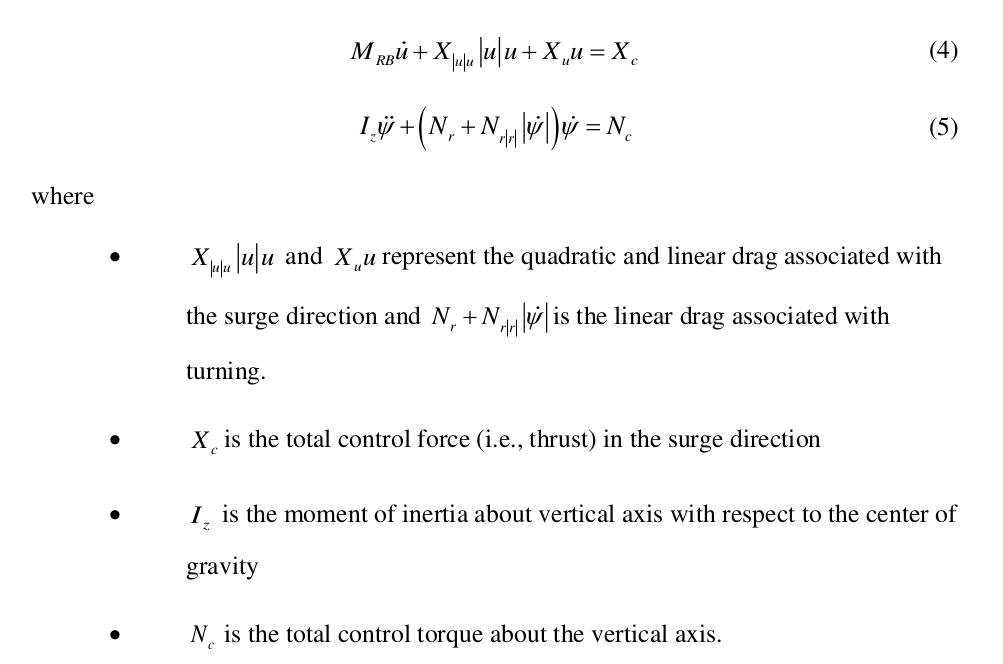

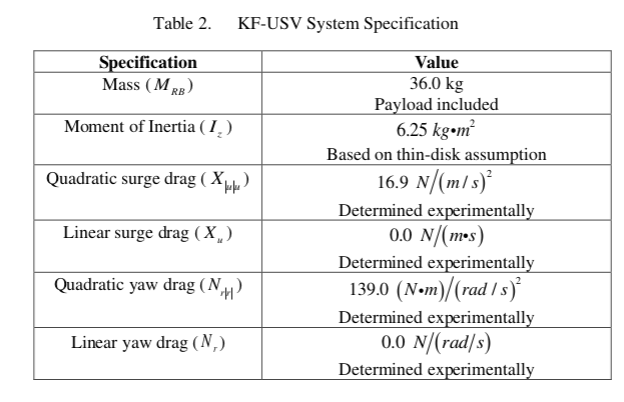

function dxdt = usv_pd(t, x, pd)
    if nargin < 3
        P = 1000;
        D = 0;
    else
        P = pd(1);
        D = pd(2);
    end
    Iz = 6.25;
    Nrr = 50;
    Nr = 0;
    yg = 1;
    y = x(1);
    dy = x(2);
    Nc = (yg - y)*P - dy*D;
    dxdt(1,1) = dy;
    dxdt(2,1) = 1/Iz*( -1*(Nr + Nrr*abs(dy))*dy + Nc);
end



dxdt = usv_pd(0, [0 0])

dxdt =      0
   160


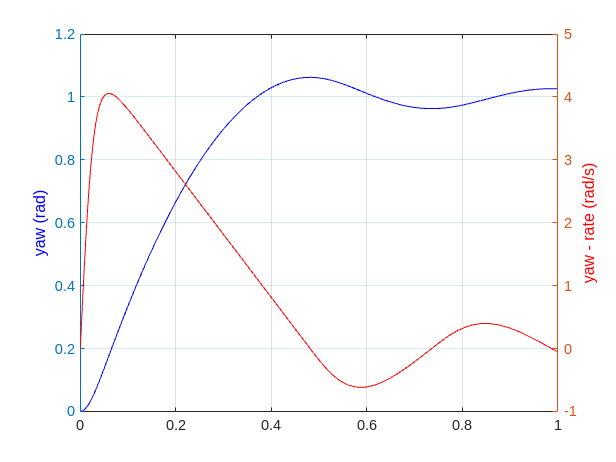

[tt, xx] = ode45(@usv_pd, [0 1], [0; 0]);
figure;
clf;
yyaxis left
plot(tt,xx(:,1), 'b')
ylabel('yaw (rad)', 'Color', 'b')
grid('on')
yyaxis right
plot(tt,xx(:,2), 'r')
ylabel('yaw - rate (rad/s)', 'Color','r')


si = stepinfo(xx(:,1),tt)

si = struct with fields:
         RiseTime: 0.2735
    TransientTime: 0.8836
     SettlingTime: 0.8836
      SettlingMin: 0.9360
      SettlingMax: 1.0625
        Overshoot: 3.5437
       Undershoot: 0
             Peak: 1.0625
         PeakTime: 0.4838


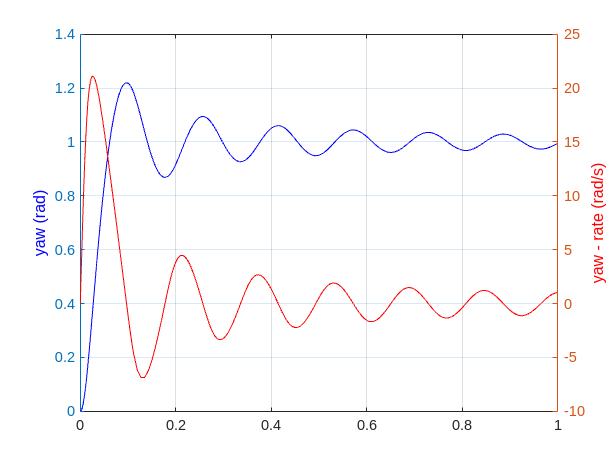


pd = [10000 0];
odefun = @(t,y) usv_pd(t, y, pd);
[tt, xx] = ode45(odefun, [0 1], [0; 0]);
figure;
clf;
yyaxis left
plot(tt,xx(:,1), 'b')
ylabel('yaw (rad)', 'Color', 'b')
grid('on')
yyaxis right
plot(tt,xx(:,2), 'r')
ylabel('yaw - rate (rad/s)', 'Color','r')




function cost = pd_performance(pd)
    odefun = @(t,y) usv_pd(t, y, pd);
    [tt, xx] = ode45(odefun, [0 1], [0; 0]);
    si = stepinfo(xx(:,1),tt);
    cost = si.RiseTime; %+ si.Overshoot/100;
end

pd0 = [1000; 0];
c = pd_performance(pd0)

c = 0.1254


[pd_opt, cost_opt] = fminsearch(@pd_performance, pd0)

pd_opt = 1.0e+03 *

    1.0487
   -0.1663


cost_opt = 1.6365e-08

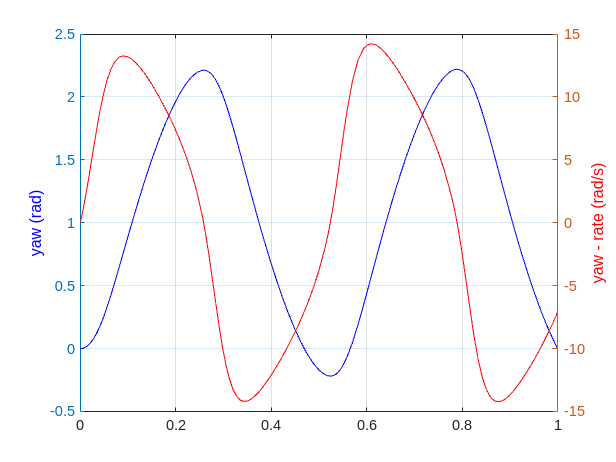

odefun = @(t,y) usv_pd(t, y, pd_opt);
[tt, xx] = ode45(odefun, [0 1], [0; 0]);
figure;
clf;
yyaxis left
plot(tt,xx(:,1), 'b')
ylabel('yaw (rad)', 'Color', 'b')
grid('on')
yyaxis right
plot(tt,xx(:,2), 'r')
ylabel('yaw - rate (rad/s)', 'Color','r')

stepinfo(xx(:,1),tt)

ans = struct with fields:
         RiseTime: 1.6365e-08
    TransientTime: 0.9940
     SettlingTime: 1.0000
      SettlingMin: -0.2197
      SettlingMax: 2.2199
        Overshoot: 1.4921e+08
       Undershoot: 1.5078e+09
             Peak: 2.2199
         PeakTime: 0.7876
